clc; clear; close all;

data = readtable("M:\Daniela's things\Github\SpectraDerma\BTViz\new_data\spectadata\spectraderama_data_2025-03-25.csv");

%disp(data)

time = data.id;
time = cell2mat(time);
time = string(time);

newtime = cellfun(@(x) extractBetween(x, 12, 19), time, 'UniformOutput', true);

%disp(newtime)

ch0 = data.data_0;
ch1 = data.data_1;
ch2 = data.data_2;
ch3 = data.data_3;
ch4 = data.data_4;
ch5 = data.data_5;

ch0_new = fillmissing(ch0, 'previous');
ch1_new = fillmissing(ch1, 'previous');
ch2_new = fillmissing(ch2, 'previous');
ch3_new = fillmissing(ch3, 'previous');
ch4_new = fillmissing(ch4, 'previous');
ch5_new = fillmissing(ch5, 'previous');


newtime = cell2mat(newtime);


newtime = string(newtime);
%class(newtime);
dateTime = datetime(newtime, 'InputFormat', 'HH:mm:ss');

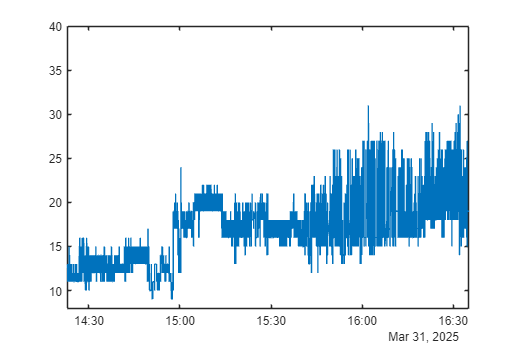

figure('Position', [100, 100, 1200, 800]);
plot(dateTime, ch1_new)
ylim([8 40])
xlim([datetime(2025, 3, 31, 14, 23, 0) datetime(2025, 3, 31, 16, 35, 0)])

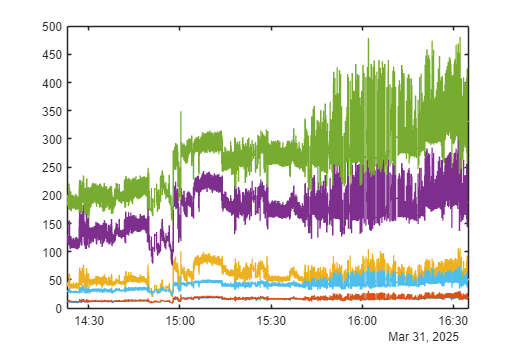


% figure('Position', [100, 100, 1200, 800]);
% plot(dateTime, ch1_new)
% ylim([8 40])
% xlim([datetime(2025, 3, 31, 14, 23, 0) datetime(2025, 3, 31, 17, 35, 0)])

all_channels = [ch0_new, ch1_new ch2_new ch3_new ch4_new ch5_new];

figure('Position', [100, 100, 1200, 800]);
plot(dateTime, all_channels)
%ylim([8 40])
xlim([datetime(2025, 3, 31, 14, 23, 0) datetime(2025, 3, 31, 16, 35, 0)])